# Lab 4: Noise and Filtering

close all; clear; clc;
I = im2double(rgb2gray(imread('peppers.png')));

## 1) Add different noise types

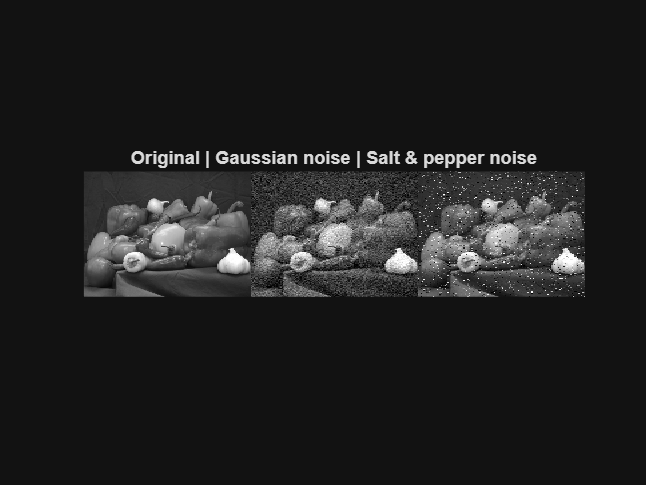

I_gauss = imnoise(I,'gaussian',0,0.01);
I_sp = imnoise(I,'salt & pepper',0.05);
figure; montage({I, I_gauss, I_sp},'Size',[1 3]);
title('Original | Gaussian noise | Salt & pepper noise');

## 2) Compute simple quality metrics

MSE_gauss = immse(I_gauss, I);
MSE_sp = immse(I_sp, I);
fprintf('MSE Gaussian: %.4f | MSE S&P: %.4f\n', MSE_gauss, MSE_sp);

MSE Gaussian: 0.0096 | MSE S&P: 0.0158


## 3) Linear filtering (mean, Gaussian)

h_avg = fspecial('average',3);
I_avg_gauss = imfilter(I_gauss,h_avg,'replicate');
I_avg_sp = imfilter(I_sp,h_avg,'replicate');
h_gauss = fspecial('gaussian',[3 3],0.7);
I_gauss_gauss = imfilter(I_gauss,h_gauss,'replicate');

## 4) Non-linear filtering (median)

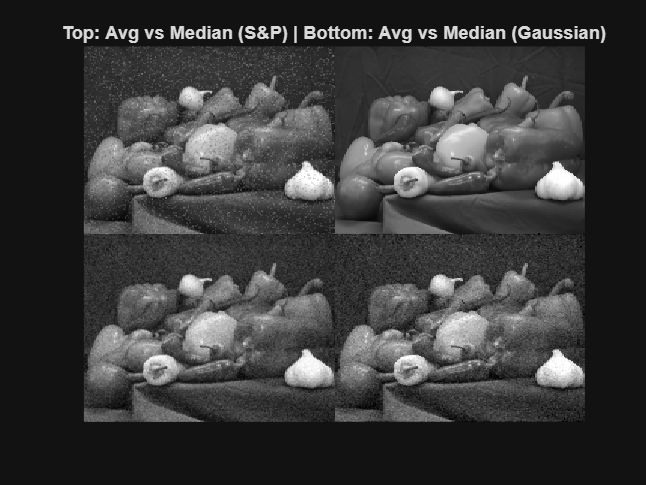

I_med_gauss = medfilt2(I_gauss,[3 3]);
I_med_sp = medfilt2(I_sp,[3 3]);
figure; montage({I_avg_sp, I_med_sp, I_avg_gauss, I_med_gauss},'Size',[2 2]);
title('Top: Avg vs Median (S&P) | Bottom: Avg vs Median (Gaussian)');

## 5) Compare metrics after filtering

fprintf('After filtering, MSE S&P avg=%.4f, med=%.4f\n',...
    immse(I_avg_sp,I), immse(I_med_sp,I));

After filtering, MSE S&P avg=0.0021, med=0.0001


## 6) Reflections

- Which noise is best removed by median filter? Why? 

    Salt and pepper noise is, because the noise consists of brightest and darkest pixels, and using median filter can easily remove them.

- Why does linear filtering blur edges more? 

    Because it ignores the edges.

- How could we design adaptive filters to preserve detail?

    We can combine edge detection with noise filtering.